Equation coefficients:


   -0.0649   -0.0429    0.2408    0.3536    0.6213



Residual error at 1.72 mM:


  -2.2204e-16



Residual sum of squares:


    0.3295



R^2 value:


    0.8576



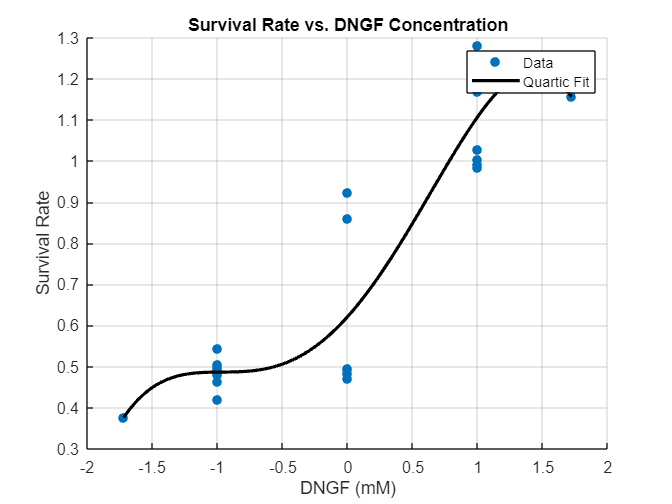

Survival rate at 5 mM: -37.4887


Survival rate at -5 mM: -30.3014


Estimated survival rate at 0.5 mM: 0.31116


Transformed model predictions:


At 5 mM: 2.6019


At -5 mM: 0


DNGF = [1, 1, 1, 1, -1, -1, -1, -1, 1, 1, 1, 1, -1,     -1, -1, -1, 0, 0, 0, 0, 0, 0, 1.72, -1.72];

SurvRate = [0.984, 1.168, 1.004, 1.184, 0.496, 0.48, 0.544, 0.5, 1.028, 1.28, 0.992, 1.224, 0.464, 0.484, 0.42, 0.504, 0.86, 0.924, 0.492, 0.484, 0.472, 0.496, 1.156, 0.376];

%a
figure;
scatter(DNGF, SurvRate, 'filled');
xlabel('DNGF (mM)');
ylabel('Survival Rate');
title('Survival Rate vs. DNGF Concentration');
grid on;

%b
p = polyfit(DNGF, SurvRate, 4); % Quartic fit
disp('Equation coefficients:');
disp(p);

%c
predicted = polyval(p, 1.72);
actual = 1.156; % From the data
res_error = actual - predicted;
disp('Residual error at 1.72 mM:');
disp(res_error);

%d
pred_all = polyval(p, DNGF);
residuals = SurvRate - pred_all;
ET = sum(residuals.^2);
disp('Residual sum of squares:');
disp(ET);

%3
SS_tot = sum((SurvRate - mean(SurvRate)).^2);
SS_res = sum((SurvRate - pred_all).^2);
R2 = 1 - SS_res/SS_tot;
disp('R^2 value:');
disp(R2);

%f
hold on;
fitted_x = linspace(min(DNGF), max(DNGF), 100);
fitted_y = polyval(p, fitted_x);
plot(fitted_x, fitted_y, '-k', 'LineWidth', 2);
legend('Data', 'Quartic Fit');
hold off;

%g
pred_5mM = polyval(p, 5);
pred_neg5mM = polyval(p, -5);
disp(['Survival rate at 5 mM: ', num2str(pred_5mM)]);
disp(['Survival rate at -5 mM: ', num2str(pred_neg5mM)]);

%h
estimated_05mM = interp1(SurvRate, 0.5, 'spline');
disp(['Estimated survival rate at 0.5 mM: ', num2str(estimated_05mM)]); 

% Bonus
NGF = DNGF + 5; % Adjust DNGF to NGF by 5 mM base concentration
logSR = log(SurvRate);
logNGF = log(NGF);
coeffs = polyfit(logNGF, logSR, 1);
A = exp(coeffs(2));
M = coeffs(1);
predict_5 = A * (10^M); % For NGF = 10 mM (5 mM)
predict_neg5 = A * (0^M); % For NGF = 0 mM (-5 mM)

disp('Transformed model predictions:');
disp(['At 5 mM: ', num2str(predict_5)]);
disp(['At -5 mM: ', num2str(predict_neg5)]);


